# TPA 1 Grupo 10

## Control con 2DOF-PID

clear all; close all; clc;
s=tf('s');
model_6 = 1/(( (10e3)*(10e-6)*s + 1 )^6)


model_6 =
 
                                   1
  --------------------------------------------------------------------
  1e-06 s^6 + 6e-05 s^5 + 0.0015 s^4 + 0.02 s^3 + 0.15 s^2 + 0.6 s + 1
 
Continuous-time transfer function.
Model Properties


Se carga el modelo de orden 1 y se muestra en comparación al de orden 6 'medido'

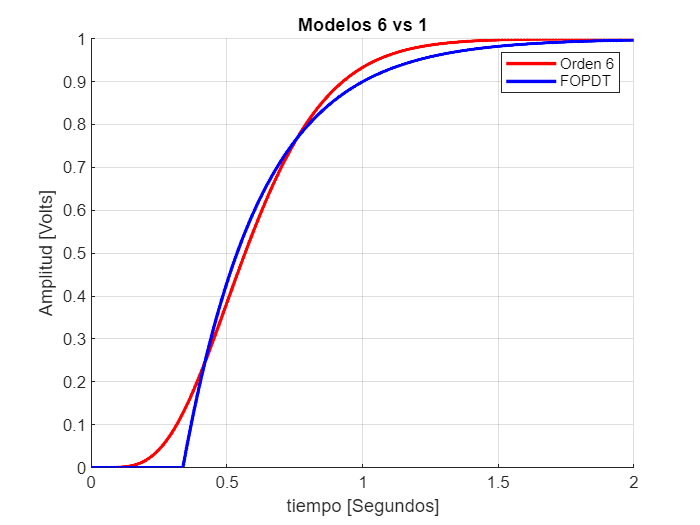

L = 0.33791;
T = 0.28802;
fopdt = 1/(s*T+1);
fopdt.inputDelay = L;

time_vector = 0:1e-3:2;
[y1] = step(model_6, time_vector);
[y2] = step(fopdt, time_vector);

figure; hold on; grid on;
plot(time_vector, y1, 'r', 'LineWidth', 2);
plot(time_vector, y2, 'b', 'LineWidth', 2);

title('Modelos 6 vs 1');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend('Orden 6', 'FOPDT');


fprintf('EMC del FOPDT: %.3f\n', immse(y1, y2));

EMC del FOPDT: 0.001


La idea es tener un controlador con filtro como el siguiente: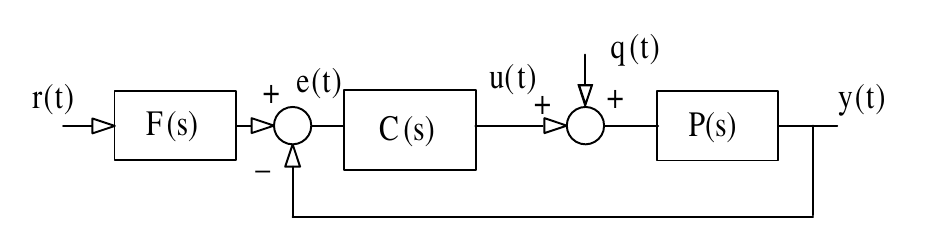

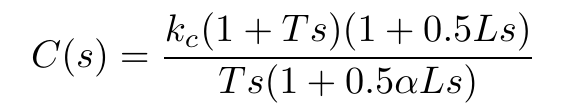

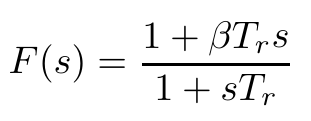

El ajuste de los valores del controlador y el filtro se hacen en base al modelo FOPDT de la planta, y luego quedan como parámetros de ajuste de robustez y performance $\alpha \;y\;\beta$

  se elige para eliminar el efecto del cero dominante

T0=0.1;
beta=0.3;

Kc=T/(L+T0);
alpha=1/(1+L/T0);
C=Kc*(1+T*s)*(1+0.5*L*s)/(T*s*(1+0.5*alpha*L*s))


C =
 
  0.03201 s^2 + 0.3006 s + 0.6577
  -------------------------------
       0.01111 s^2 + 0.288 s
 
Continuous-time transfer function.
Model Properties


F=(1+beta*L*0.5*s)/(1+s*L*0.5)


F =
 
  0.05069 s + 1
  -------------
   0.169 s + 1
 
Continuous-time transfer function.
Model Properties


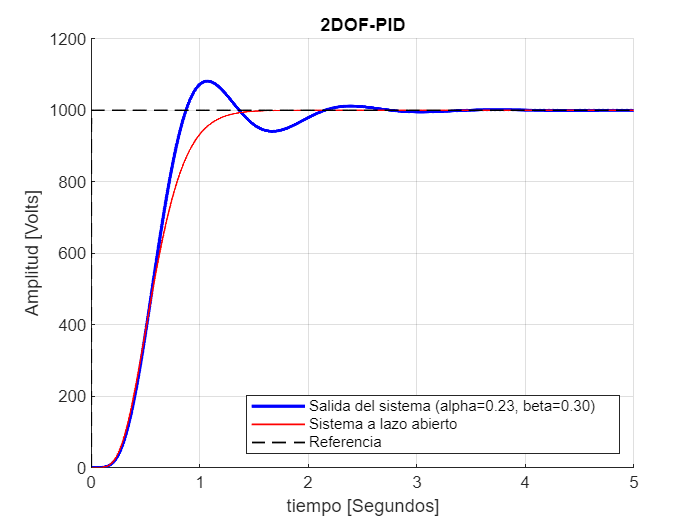


time_vector = 0:1e-3:5;
reference = 1000*ones(1, length(time_vector)); reference(1)=0;

closed_loop_system = F*C*model_6/(1+C*model_6);
% perturbance=zeros(1, length(time));perturbance(round(length(perturbance)*0.75):end)=0.2;
% reference=reference-perturbance;
[y] = lsim(closed_loop_system, reference, time_vector);
[y_ol] = lsim(model_6, reference, time_vector);

figure; hold on; grid on;
plot(time_vector, y, 'b', 'LineWidth', 2);
plot(time_vector, y_ol, 'r', 'LineWidth', 1);
plot(time_vector, reference, '--k', 'LineWidth', 1);

title('2DOF-PID');
ylabel('Amplitud [Volts]');
xlabel('tiempo [Segundos]');
legend(sprintf('Salida del sistema (alpha=%.2f, beta=%.2f)', alpha, beta), 'Sistema a lazo abierto', 'Referencia', 'Location', 'southeast');

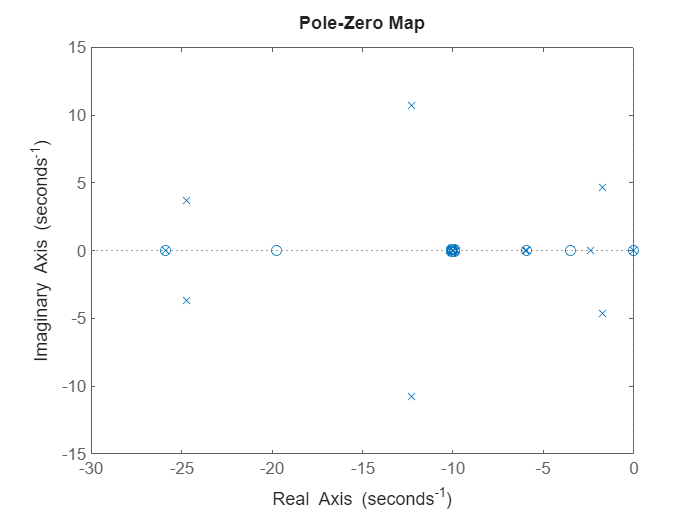


figure()
pzmap(closed_loop_system)